# **Project 1 - Mask Effectivness**

**By Michaela Fox and Ashley Yang**

## **Question**

Our motivating question is how effective do masks need to be to cut the peak number of infected persons by 50%? This is a predictive type of question, since we are trying to predict the number of future infected persons based on mask effectiveness. We believe this to be an important question as knowing the impact of mask effectiveness gives us more information to work with about how to best protect people in times of illness. For instance, mask companies may use this information to adjust their manufacturing process of masks to better fit the necessary mask effectivity value.

In order to understand this motivating question and our modeling choices, we needed to have more background information on what “mask effectivity” means, as well as the existing kinds of masks with their corresponding effectivity. Our literature search results are as follows:

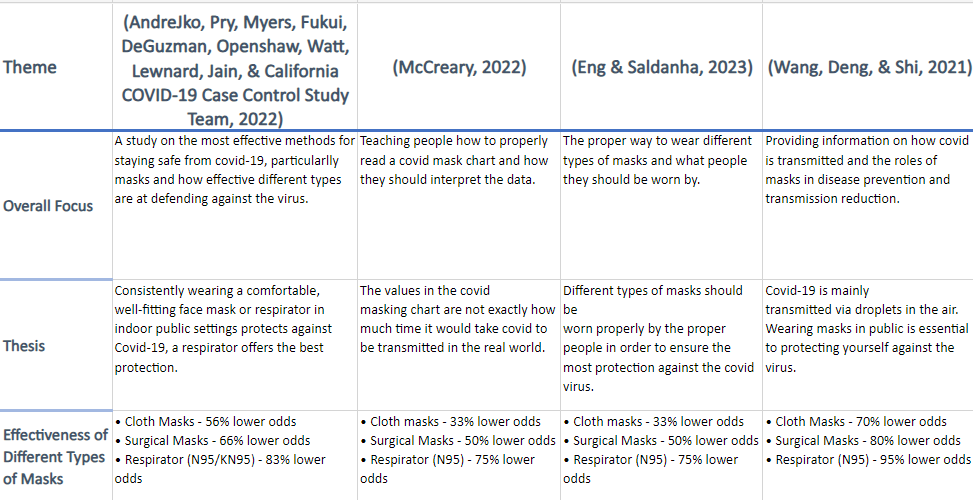

## **Methodology/Model**

	Our model is as follows: 

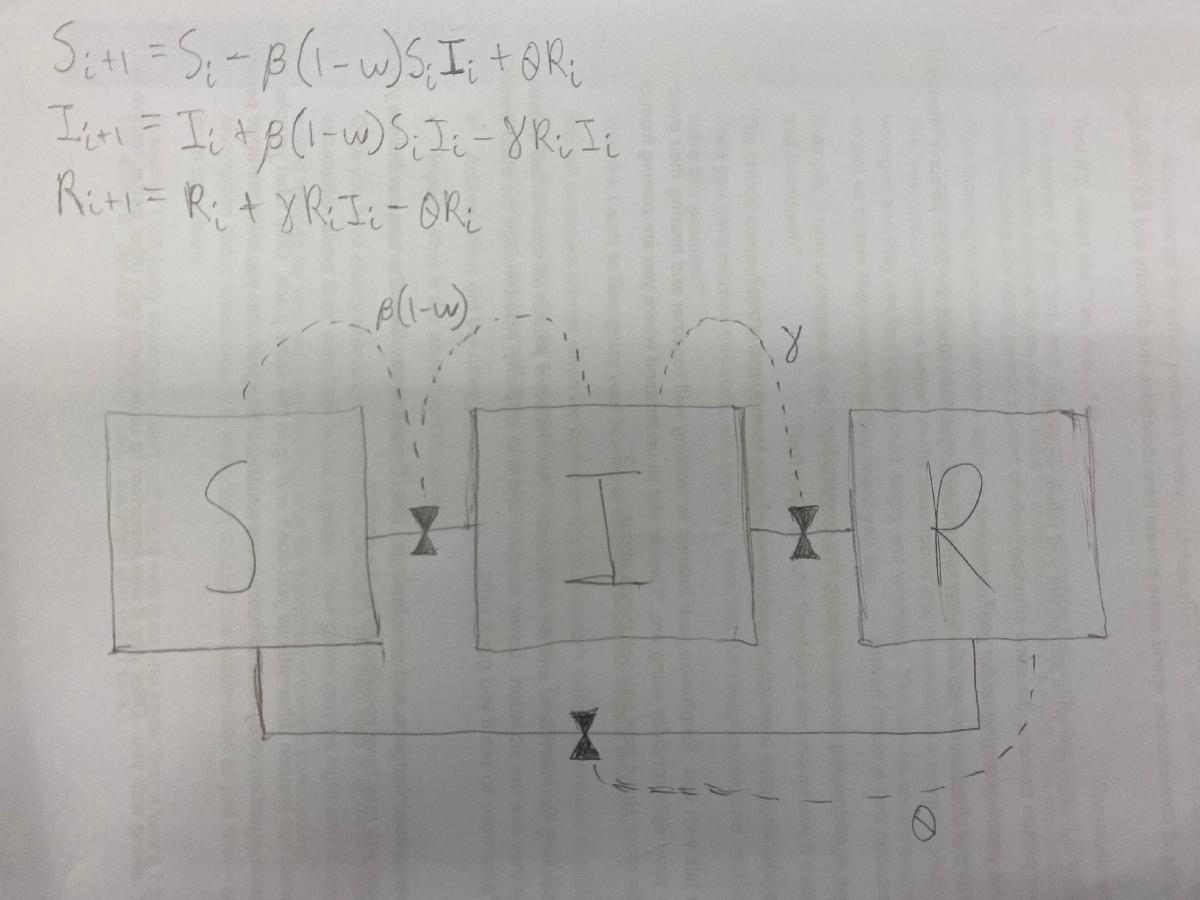

    We made the assumption that everyone in our model is wearing the same type of mask constantly, in order to simplify external factors and just focus on mask effectiveness itself. Each stock represents the following: the “S” stock represents the amount of susceptible people, the “I” stock represents the amount of infected people, the “R” stock represents the amount of recovered people. Each flow represents the following: the “beta(1 - omega)” flow represents the infection rate (where beta represents the raw infection rate--for instance a beta value of 1/88 means that 1 out of 88 people in contact with an infected persons becomes infected--and omega represents the effectivity percentage of masks), the “gamma” flow represents the recovery rate (where a gamma of 1/2 means it takes 2 weeks to recover), and the “theta” flow represents the reinfectivity rate. 

    We set the parameters of our model based on thinking about how people would possibly move between the S, I, and R stocks. For instance, in thinking about our unique parameter ω, the effectiveness percentage of masks, we figured that mask wearing would slow down the rate of people moving from susceptible to infected. Therefore, ω was set as a flow between S and I, where, based on our background research, it represents an effectivity percentage through "lowering odds" of infection. This is then how we obtained our infection rate calculation of beta(1 - omega), as we are really multiplying our beta against mask ineffectivity to get a lower infection rate that simulates this "lowering odds" (the mask ineffectivity comes from the mathematical logic of a lower effectivity rate giving less of a decrease in infection rate, and so needing to multiply by 1 - effectivity to actually follow that). 

    The verification facts that we came up with for our model were that the total number of people (100) stays the same throughout the model and the number of each stock doesn’t go below 0. We used the following assert() statements to implement our verification facts:

%assert(all(abs(T - 100) < 1e-3), 'Total is off'); % to verify that the total number of people stays at 100 throughout the model
%assert(min(S) >= 0, 'S shouldnt go below 0'); % 3 statements to verify that each of the 3 stocks doesn't go below 0
%assert(min(I) >= 0, 'I shouldnt go below 0');
%assert(min(R) >= 0, 'R shouldnt go below 0');

## **Result**

Without masks, this is our curve with the original data:

% Original simulation
beta = 1 / 88; % Infection rate (New / Susceptible / Infected / day)
gamma = 1 / 2; % Recovery rate (1 / day)
theta = 1 / 62; % Re-suspectible rate 1 / days
week_end = 100;
i_1 = 2;       % Initial count of infected persons
s_1 = 100 - i_1;
r_1 = 0;

[S_two, I_two, R_two, W_two] = simulate_sir_v3(s_1, i_1, r_1, beta, gamma, theta, week_end);

Unrecognized function or variable 'simulate_sir_v3'.


% Plot the fitted simulation
figure()
plot(W_two, I_two, 'k-', 'LineWidth', 1, 'DisplayName', 'Original'); hold on
%plot(W_two, S_two, 'DisplayName', 'S')
%plot(W_two, R_two, 'DisplayName', 'R')
xlabel("Time (Weeks)")
ylabel("Infected Persons")
legend()
title("Original Simulation of Infection Over Time")
I_max = max(I_two);
I_half = I_max / 2; % half of infected peak

The metric we chose was the peak number of infected persons, as that one number tells us what effectiveness value suffices to answer our question. Namely, when determining what effectiveness value we need, we can look to our metric to see if we met half of the peak number of infected persons. The results we generated using our model, as shown below, were that masks needed to be 26% effective at protecting against the virus to decrease the max number of infected by half.

% overall graph again but with masked included
betaM = 1 / 88; % Infection rate (New / Susceptible / Infected / day)
gammaM = 1 / 2; % Recovery rate (1 / day)
thetaM = 1 / 62; % Re-suspectible rate 1 / days
omega = 0.2626; % effectivity
beta1 = betaM * (1 - omega); 
week_end = 200;
i_1 = 2;       % Initial count of infected persons
s_1 = 100 - i_1;
r_1 = 0;
I_max = max(I_two);
I_half = I_max / 2; % half of infected peak

[S, I, R, W] = simulate_sir_v3(s_1, i_1, r_1, beta, gamma, theta, week_end);
[S_mask, I_mask, R_mask, W_mask] = simulate_sir_v3(s_1, i_1, r_1, beta1, gamma, theta, week_end);
T_mask = S_mask + I_mask + R_mask;

% Plot the fitted simulation
figure()
plot(W, I, 'k-', 'LineWidth', 1, 'DisplayName', 'Original'); hold on
plot(W_mask, I_mask, 'r-', 'LineWidth', 1, 'DisplayName', 'Masked');
%plot(W_two, S_two, 'DisplayName', 'S')
%plot(W_two, R_two, 'DisplayName', 'R')
xlabel("Time (Weeks)")
ylabel("Infected Persons")
legend()
title("Simulation of Infection Over Time, Original Versus Masked")
% assert statements
assert(all(abs(T_mask - 100) < 1e-3), 'Total is off');
assert(min(S) >= 0, 'S shouldnt go below 0');
assert(min(I) >= 0, 'I shouldnt go below 0');
assert(min(R) >= 0, 'R shouldnt go below 0');

This is our parameter sweep using our chosen metric of mask ineffectiivty (represented by omega), which we used to find the value of omega that would give us our metric value determined above. 

% Parameter sweep
% Sweep above and below the nominal values
Alpha_all = linspace(0, 1, 100); % ineffectivity
Omega_all = 1 - Alpha_all; % effectivity
Beta_all = beta * (1 - Omega_all)

Max_all = zeros(size(Beta_all));
for i = 1:100
    beta_temp = Beta_all(i);
    [S, I, R, W] = simulate_sir(s_1, i_1, r_1, beta_temp, gamma, week_end);
    Max_all(i) = max(I);
end 

index = find(abs(Max_all - I_half) < 0.5, 1); % find which value gets you half the peak
Omega_Desired = Omega_all(index) % least omega point that gets you half infected

figure
plot(Omega_all, Max_all, 'r'); hold on
plot(Omega_Desired, I_half, 'kx', 'LineWidth', 6); % plotting which effectivity value gets you half
xlabel('Effectivity (\omega)')
ylabel('Max Infected')
title("Parameter Sweep of Effectivity to Find Half of Peak")

The most important trends in our parameter sweep were that there is a linear increase in the max number of infected people as ineffectivity of masks increases from 0.5 to 1. If ineffectivity is less than about 0.5 then there is no change to the max number of infected people. These results mean that masks need to be 26% effective at protecting against the virus to decrease the max number of infected people by half.

## **Interpretation**

    We were interested in figuring out how effective do masks need to be to cut the peak number of infected persons by 50%. To this question, our model results tell us that masks need to be 26% effective to cut the peak number of infected individuals by 50%. The limitations of our model are primarily that it cannot predict how many people are wearing masks or what kind of masks they are wearing. In the future, we might try and implement different types of masks to see which ones are best at protecting against the virus and can further decrease the max number of infected, possibly by 75%. We might also try and see how many people need to be wearing masks to cut the max number of infected by 50%.